clc; clear;
a = 5; b = 4; T1 = 80; max_term = 100

max_term = 100

syms x y n
T(x,y,n) = (4 * T1 / sym(pi)) * ...
    (sin((2 * n - 1)*(sym(pi) * x / a)) * sinh((2 * n - 1)*(sym(pi) * y / a))) / ...
    ((2 * n - 1) * sinh((2 * n - 1) * (sym(pi) * b / a)))

$$T(x, y, n) = \frac{320\,\sin\left(\frac{\pi \,x\,\left(2\,n-1\right)}{5}\right)\,\sinh\left(\frac{\pi \,y\,\left(2\,n-1\right)}{5}\right)}{\pi \,\sinh\left(\frac{4\,\pi \,\left(2\,n-1\right)}{5}\right)\,\left(2\,n-1\right)}$$

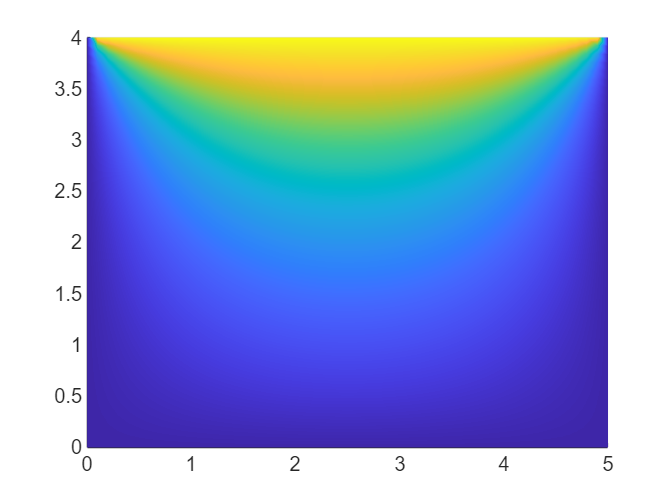


t = matlabFunction(T);

xspan = linspace(0, a, 50);
yspan = linspace(0, b, 50);

[X, Y] = meshgrid(xspan, yspan);

arr = zeros(length(yspan), length(xspan));

for n = 1 : max_term
    arr = arr + t(X, Y, n);
end

surf(X, Y, arr)
shading interp;
view(2)